Let's make a 3 pixel x 3 pixel image

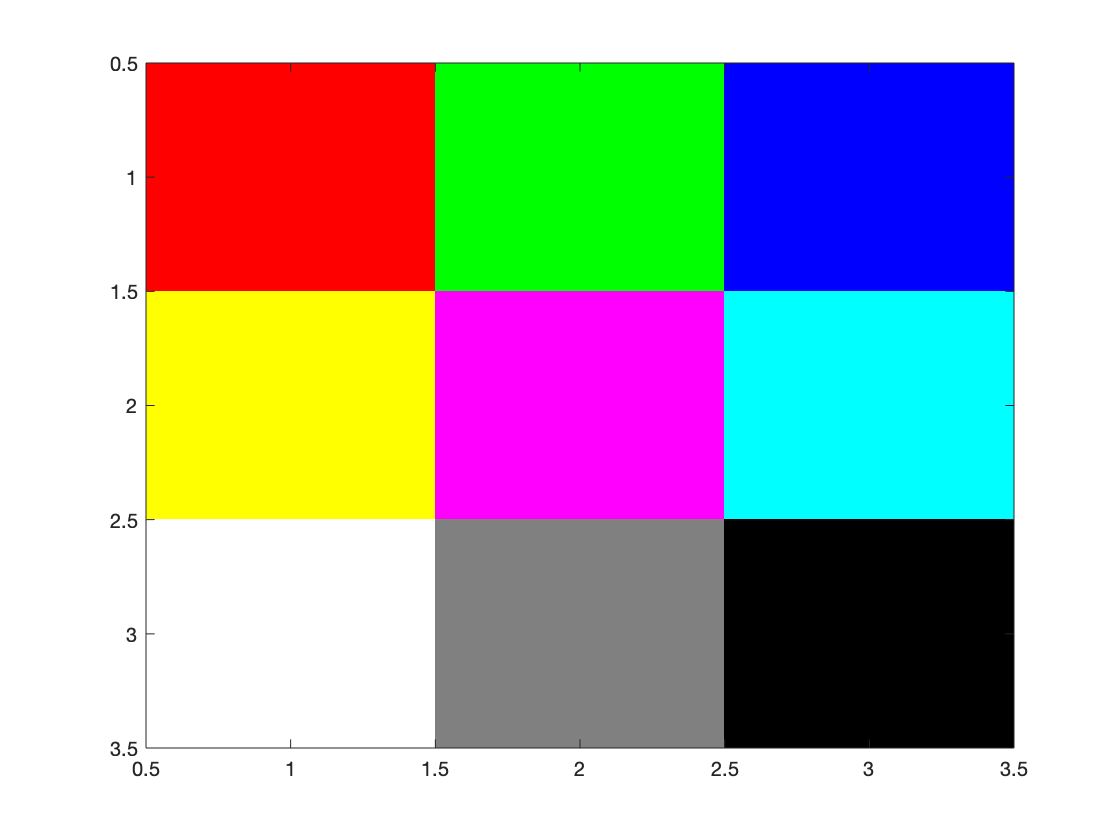

clc
clear

%Red Layer
img(1:3,1:3,1) = uint8([255 0 0
                  255 255 0
                  255 128 0]);

%Green Layer              
img(1:3,1:3,2) = uint8([0 255 0
                  255 0 255
                  255 128 0]);              

%Blue Layer              
img(1:3,1:3,3) = uint8([0 0 255
                  0 255 255
                  255 128 0]);

%Take a look            
image(img)  


%First Try
% imgR = img(:,:,1)
% imgG = img(:,:,2)              
% imgB = img(:,:,3)
% 
% mR = imgR>128
% mG = imgG<128
% mB = imgB<128
% 
% m = mR & mG & mB
% 
% 
% img(:,:,1) = imgR.*m;
% img(:,:,2) = imgG.*m;
% img(:,:,3) = imgB;
% 
% img

%Second Try
%Make a layer 2D mask by ANDing the desired RGB pixel ranges
m = img(:,:,1)<128 & img(:,:,2)>128 & img(:,:,3)<128

m = 3×3 logical array
   0   1   0
   0   0   0
   0   0   0



%Turn the 2D mask into a 3D mask by copying it to each RGB Layer
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
m3

m3 = 3×3×3 logical array
m3(:,:,1) =

   0   1   0
   0   0   0
   0   0   0


m3(:,:,2) =

   0   1   0
   0   0   0
   0   0   0


m3(:,:,3) =

   0   1   0
   0   0   0
   0   0   0



m3 = cat(3,m,m,m);


%Apply mask to set chosen pixels to appropriate values
% img
newImg = uint8(~m3*255)

newImg = 3×3×3 uint8 array
newImg(:,:,1) =

   255     0   255
   255   255   255
   255   255   255


newImg(:,:,2) =

   255     0   255
   255   255   255
   255   255   255


newImg(:,:,3) =

   255     0   255
   255   255   255
   255   255   255


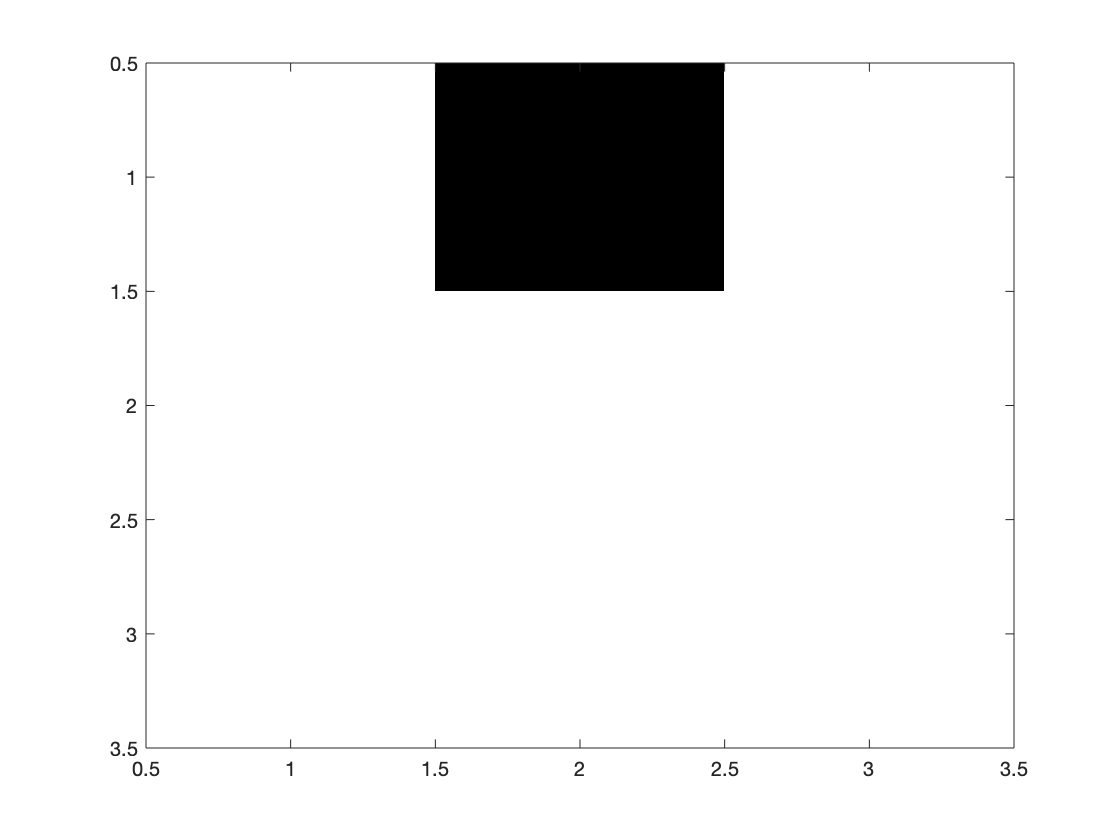

% img(~m3)
% img(m3) = 255


%Show image
image(newImg)            